# **PARCIAL 3**

- `Gerson Alexander Sanchez Brito - 2192987`

- `Juan Sebastian Avila Diaz - 2200524`

clc, clear all, close all

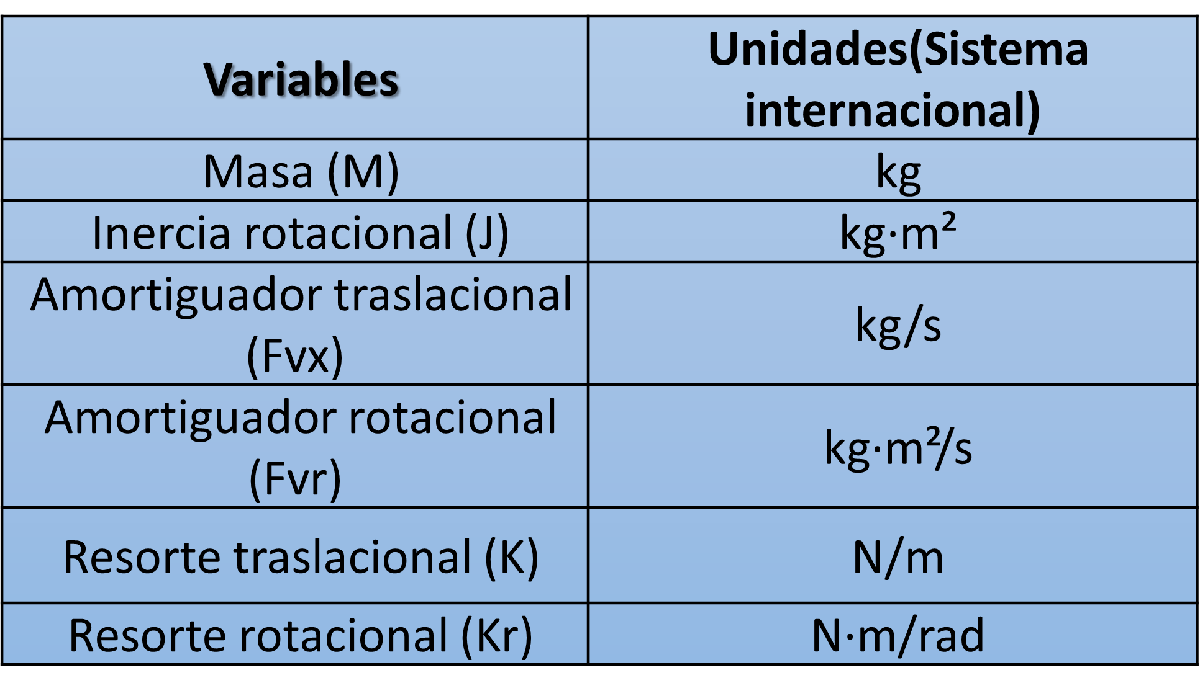

**1) Para el siguiente sistema  modélelo utilizando la ecuación  de Euler-Lagrange:**

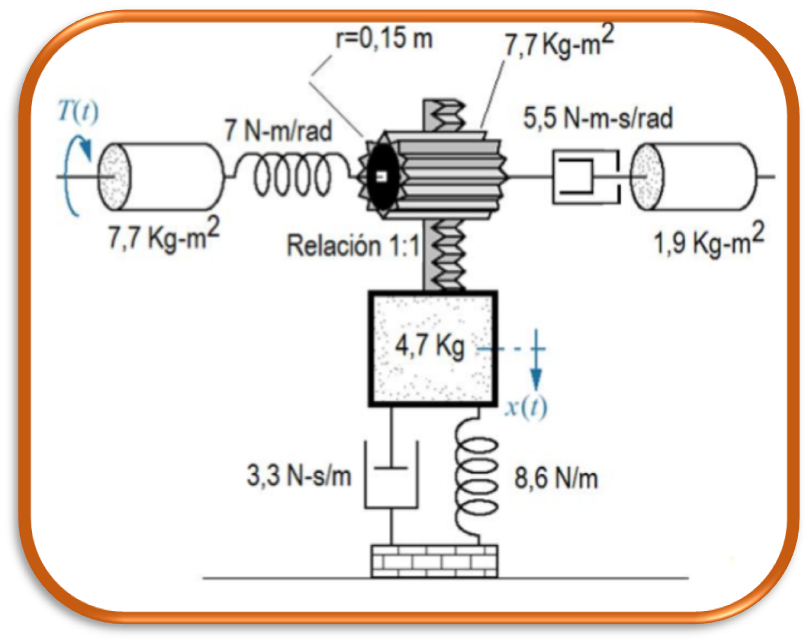

syms th1 th2 th3 x Dth1 Dth2 Dth3 Dx DDth1 DDth2 DDth3 DDx tt1 Dtt1 y Dy DDy th Dth DDth
syms T0 T1 DT1 t
syms J1 J2 J3 Kr Fvr r M K Fvx
syms m1 m2  
syms L g
syms q1 q2 q3 q4 q5 q6 Dq2 Dq4 Dq6 
%syms q(1) q(2) q(3) q(4) q(5) q(6)
%g = 9.81;
%m1 = 15*exp(-0.01*x*y*th*t)
%m2 = 1.5*exp(0.01*x*y*th*t)

***Energia Cinetica y Potencial***

T = (1/2)*(m1*Dx^2)+(1/2)*(m1*Dy^2)+(1/2)*(m2*(Dx-(L)*Dth*sin(th))^2)+(1/2)*(m2*(Dy+(L)*Dth*cos(th))^2)

$$T = \frac{{\mathrm{Dx}}^{2}\,m_{1}}{2}+\frac{{\mathrm{Dy}}^{2}\,m_{1}}{2}+\frac{m_{2}\,{\left(\mathrm{Dy}+\mathrm{Dth}\,L\,\cos\left(\mathrm{th}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left(\mathrm{Dx}-\mathrm{Dth}\,L\,\sin\left(\mathrm{th}\right)\right)}^{2}}{2}$$

V = m1*g*y + m2*g*(y+L*sin(th));
D = 0;

***Lagrangiano***

Lag = T - V

$$Lag = \frac{{\mathrm{Dx}}^{2}\,m_{1}}{2}+\frac{{\mathrm{Dy}}^{2}\,m_{1}}{2}+\frac{m_{2}\,{\left(\mathrm{Dy}+\mathrm{Dth}\,L\,\cos\left(\mathrm{th}\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left(\mathrm{Dx}-\mathrm{Dth}\,L\,\sin\left(\mathrm{th}\right)\right)}^{2}}{2}-g\,m_{2}\,\left(y+L\,\sin\left(\mathrm{th}\right)\right)-g\,m_{1}\,y$$

***Coordenadas generalizadas***

q  = [x, y, th];
Dq = [Dx, Dy, Dth];

***Fuerzas Externas ***

F = [0, 0, 0, 0]; % Torque1 debido al movimiento angular de la inercia/piñon 2
tt = linspace(0, 500, 5000);

***Solución Metodo Euler - Lagrange***


$$\frac{d}{\textrm{dt}\;}\left(\frac{\partial L}{\partial \dot{q_i } }\right)-\frac{\partial L}{\partial q_i }+\frac{\partial D}{\partial \dot{q_i } }=F$$


***y usando funcion desarrollada por torabi***

Eq = simplify(LagrangeDynamicEqDeriver(Lag, D, F, q, Dq))

$$Eq = \left(\begin{array}{c} \mathrm{DDx}\,m_{1}-\frac{m_{2}\,\left(2\,L\,\cos\left(\mathrm{th}\right)\,{\mathrm{Dth}}^{2}-2\,\mathrm{DDx}+2\,\mathrm{DDth}\,L\,\sin\left(\mathrm{th}\right)\right)}{2}\\ \mathrm{DDy}\,m_{1}+g\,m_{1}+g\,m_{2}+\frac{m_{2}\,\left(-2\,L\,\sin\left(\mathrm{th}\right)\,{\mathrm{Dth}}^{2}+2\,\mathrm{DDy}+2\,\mathrm{DDth}\,L\,\cos\left(\mathrm{th}\right)\right)}{2}\\ L\,m_{2}\,\left(\mathrm{DDy}\,\cos\left(\mathrm{th}\right)-\mathrm{DDx}\,\sin\left(\mathrm{th}\right)+g\,\cos\left(\mathrm{th}\right)+\mathrm{DDth}\,L\right) \end{array}\right)$$

Eqq = simplify([subs(Eq(1),[x,Dx,DDx,y,Dy,DDy,th,Dth,DDth],[q1,q2,Dq2,q3,q4,Dq4,q5,q6,Dq6]);subs(Eq(2),[x,Dx,DDx,y,Dy,DDy,th,Dth,DDth],[q1,q2,Dq2,q3,q4,Dq4,q5,q6,Dq6]);subs(Eq(3),[x,Dx,DDx,y,Dy,DDy,th,Dth,DDth],[q1,q2,Dq2,q3,q4,Dq4,q5,q6,Dq6])])

$$Eqq = \left(\begin{array}{c} {\mathrm{Dq}}_{2}\,m_{1}-\frac{m_{2}\,\left(2\,L\,\cos\left(q_{5}\right)\,{q_{6}}^{2}-2\,{\mathrm{Dq}}_{2}+2\,{\mathrm{Dq}}_{6}\,L\,\sin\left(q_{5}\right)\right)}{2}\\ {\mathrm{Dq}}_{4}\,m_{1}+g\,m_{1}+g\,m_{2}+\frac{m_{2}\,\left(-2\,L\,\sin\left(q_{5}\right)\,{q_{6}}^{2}+2\,{\mathrm{Dq}}_{4}+2\,{\mathrm{Dq}}_{6}\,L\,\cos\left(q_{5}\right)\right)}{2}\\ L\,m_{2}\,\left({\mathrm{Dq}}_{4}\,\cos\left(q_{5}\right)-{\mathrm{Dq}}_{2}\,\sin\left(q_{5}\right)+g\,\cos\left(q_{5}\right)+{\mathrm{Dq}}_{6}\,L\right) \end{array}\right)$$

Eqm1 = simplify(Eqq(1) - (subs(Eqq(1), [Dq2,Dq4,Dq6], [0,0,0])))

$$Eqm1 = {\mathrm{Dq}}_{2}\,m_{1}+{\mathrm{Dq}}_{2}\,m_{2}-{\mathrm{Dq}}_{6}\,L\,m_{2}\,\sin\left(q_{5}\right)$$

Eqm2 = simplify(Eqq(2) - (subs(Eqq(2), [Dq2,Dq4,Dq6], [0,0,0])))

$$Eqm2 = {\mathrm{Dq}}_{4}\,m_{1}+{\mathrm{Dq}}_{4}\,m_{2}+{\mathrm{Dq}}_{6}\,L\,m_{2}\,\cos\left(q_{5}\right)$$

Eqm3 = simplify(Eqq(3) - (subs(Eqq(3), [Dq2,Dq4,Dq6], [0,0,0])))

$$Eqm3 = L\,m_{2}\,\left({\mathrm{Dq}}_{4}\,\cos\left(q_{5}\right)-{\mathrm{Dq}}_{2}\,\sin\left(q_{5}\right)+{\mathrm{Dq}}_{6}\,L\right)$$

Eqm = [Eqm1;Eqm2;Eqm3]

$$Eqm = \left(\begin{array}{c} {\mathrm{Dq}}_{2}\,m_{1}+{\mathrm{Dq}}_{2}\,m_{2}-{\mathrm{Dq}}_{6}\,L\,m_{2}\,\sin\left(q_{5}\right)\\ {\mathrm{Dq}}_{4}\,m_{1}+{\mathrm{Dq}}_{4}\,m_{2}+{\mathrm{Dq}}_{6}\,L\,m_{2}\,\cos\left(q_{5}\right)\\ L\,m_{2}\,\left({\mathrm{Dq}}_{4}\,\cos\left(q_{5}\right)-{\mathrm{Dq}}_{2}\,\sin\left(q_{5}\right)+{\mathrm{Dq}}_{6}\,L\right) \end{array}\right)$$

EqmDq2 = subs(Eqm,[Dq2,Dq4,Dq6],[1,0,0])

$$EqmDq2 = \left(\begin{array}{c} m_{1}+m_{2}\\ 0\\ -L\,m_{2}\,\sin\left(q_{5}\right) \end{array}\right)$$

EqmDq4 = subs(Eqm,[Dq2,Dq4,Dq6],[0,1,0])

$$EqmDq4 = \left(\begin{array}{c} 0\\ m_{1}+m_{2}\\ L\,m_{2}\,\cos\left(q_{5}\right) \end{array}\right)$$

EqmDq6 = subs(Eqm,[Dq2,Dq4,Dq6],[0,0,1])

$$EqmDq6 = \left(\begin{array}{c} -L\,m_{2}\,\sin\left(q_{5}\right)\\ L\,m_{2}\,\cos\left(q_{5}\right)\\ L^{2}\,m_{2} \end{array}\right)$$

Eqqd1 = simplify(- subs(Eqq(1), [Dq2,Dq4,Dq6], [0,0,0]))

$$Eqqd1 = L\,m_{2}\,{q_{6}}^{2}\,\cos\left(q_{5}\right)$$

Eqqd2 = -subs(Eqq(2), [Dq2,Dq4,Dq6], [0,0,0])

$$Eqqd2 = L\,m_{2}\,\sin\left(q_{5}\right)\,{q_{6}}^{2}-g\,m_{1}-g\,m_{2}$$

Eqqd3 = -subs(Eqq(3), [Dq2,Dq4,Dq6], [0,0,0])

$$Eqqd3 = -L\,g\,m_{2}\,\cos\left(q_{5}\right)$$

[m, n] = size(Eqq)

m = 3

n = 1

%cofactors = zeros(m, n);

% for i = 1:m
%     for j = 1:n
%         minor = Eqq;
%         minor(i, :) = [];
%         minor(:, j) = [];
%         cofactors(i, j) = (-1)^(i+j) * det(minor)
%     end
% end

%Eq = [Eq; x-th2]; % ec.auxiliar relacion longitud de arco con el radio y angulo de giro J2 debido al 
                  % movimiento rotacional de este piñon

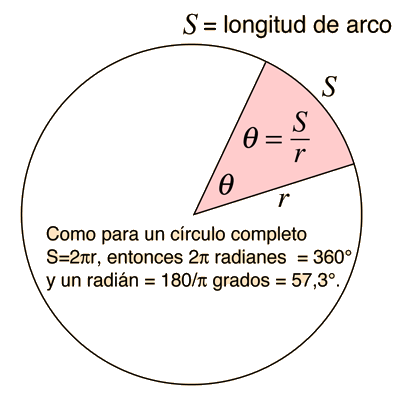

**2) Desarrolle numéricamente el modelo matemático asumiendo todas las condiciones iniciales iguales a 5.0. Analice su dinámica para **


$$T\left(t\right)=8\;\sin \left(2t-0\ldotp 2\right)$$


% % Haciendo uso de algebra para resolver el sistema de ecuaciones 
% qr = q(1:3); % se establecieron las coordenadas generalizadas deseadas a encontrar
% Dqr = Dq(1:3);
% 
% Eq2 = subs(Eq(2),T1,(solve(Eq(4),T1))); % se despejo el torque1 de la ec (4) general 
%                                         % y remplazarlo en la ec (2)
% Eqr = [Eq(1,1); Eq2; Eq(3,1)]; % Armar un nuevo sistemas
% Eqr(2) = subs(Eq2,[x,Dx,DDx],[r*th2,r*Dth2,r*DDth2]) % y usando la ecuacion auxiliar se 
%                                                      % dejo x en funcion del theta2 
%  [SSr, xxr] = DynamicEqSolver(Eqr, qr, Dqr, [J1 J2 J3 Kr Fvr r M K Fvx T0],...
%                               [7.7, 7.7, 1.9, 7.0, 5.5, 0.15, 4.7, 8.6, 3.3, 8*sin(2*t - 0.2)], tt, [5.0, 5.0, 5.0, 5.0, 5.0, 5.0]);
%  figure; 
%  S1 = sprintf('$ \\theta_1$'); 
%  S2 = sprintf('$ \\theta_2$');
%  S3 = sprintf('$ \\theta_3$');
%  
%  plot(tt,xxr(:,1),'color',[0,0.6,0],'linewidth',2); 
%  hold on; 
%  grid on;
%  plot(tt,xxr(:,2),'color',[0 0.4470 0.7410],'linewidth',2); 
%  plot(tt,xxr(:,3),'r','linewidth',2); 
%  title("Comportamiento Angulos")
%     
%  H1 = legend(S1,S2,S3); 
%  set(H1,'interpreter','latex','fontsize',18,'location','SouthWest');
%  hx = xlabel('Tiempo [s]');  set(hx, 'fontsize', 18);
%  hy = ylabel('Angulos [rad]'); set(hy, 'fontsize', 18);
%  set(gca, 'fontsize', 18);
% qx = q([1,3,4]);
% Dqx = Dq([1,3,4]);
% Eq3x = subs(Eq(2),T1,(solve(Eq(4),T1)));
% Eq3x = subs(Eq3x,[th2,Dth2,DDth2],[x/r,Dx/r,DDx/r]);
% Eq1x = subs(Eq(1),[th2,Dth2,DDth2],[x/r,Dx/r,DDx/r]);
% Eq2x = subs(Eq(3),[th2,Dth2,DDth2],[x/r,Dx/r,DDx/r]);
% Eqx = [Eq1x;Eq2x;Eq3x]; % Haciendo la misma estrategia del item anterior, se hallo el comportamiento de x(t) del sistema
%  [SSx, xxx] = DynamicEqSolver(Eqx, qx, Dqx, [J1 J2 J3 Kr Fvr r M K Fvx T0],...
%                               [7.7, 7.7, 1.9, 7.0, 5.5, 0.15, 4.7, 8.6, 3.3, 8*sin(2*t - 0.2)], tt, [5.0, 5.0, 5.0, 5.0, 5.0, 5.0]);
%                           
%  figure; %graficando resultado coordenada x
%  plot(tt,xxx(:,3),'color',[0.4940 0.1840 0.5560],'linewidth',2);
%  grid on;
%  
%  S4 = sprintf('$x$');
%  H = legend(S4); 
%  set(H,'interpreter','latex','fontsize',18,'location','SouthWest');
%  hx = xlabel('Tiempo [s]');  set(hx, 'fontsize', 18);
%  hy = ylabel('x [m]'); set(hy, 'fontsize', 18);
%  set(gca, 'fontsize', 18); 

## `Observaciones:`

- `Debido al comportamiento senosoidal de la entrada del sistema en este caso el Torque. las demas coordenadas generalizadas tienen el mismo comportamiento senosoidal durante los primeros ciclos.`

- `Sin embargo, debido a los amortiguadores rotacionales y traslacionales el comportamiento del sistema tiende a amortiguar las respuesta del sistema`

**3) Asuma ahora que la masa, las inercias, los amortiguadores traslacionales y rotacionales, así como los resortes traslacionales y los  rotacionales varían con el tiempo. Asumasus variaciones como una función exponencial de la forma**


$$J_1 =7\ldotp 7e^{\;-0\ldotp 7t}$$


% %definiendo el comportamiento de las cantidades fisicas del ejercicio
% 
% j1 = 7.7*exp(-(0.7)*t);
% j2 = 7.7*exp(-(0.7)*t);
% j3 = 1.9*exp(-(0.9)*t);
% m = 4.7*exp(-(0.7)*t);
% 
% kr = 7.0*exp(-(0.0)*t);
% k = 8.6*exp(-(0.6)*t);
% 
% fvr = 5.5*exp(-(0.5)*t);
% fvx = 3.3*exp(-(0.3)*t);
% 
% 
% T3 = (1/2)*j1*Dth1^2 + (1/2)*j2*Dth2^2 + (1/2)*j3*Dth3^2 + (1/2)*m*Dx^2;
% V3 = (1/2)*kr*(th1 - th2)^2 + (1/2)*k*(x)^2 ;
% D3 = (1/2)*fvx*Dx^2 + (1/2)*fvr*(Dth2 - Dth3)^2;

** Lagrangiano**

% L3 = T3 - V3;

***Solución metodo Euler - Lagrange, usando funcion desarrollada por torabi***

% Eq3 = LagrangeDynamicEqDeriver(L3, D3, F, q, Dq)
% Eq3 = [Eq3; x-th2];

**4) Desarrolle numéricamente el modelo matemático anterior asumiendo todas las condiciones iniciales iguales a 5.0. Analice su  dinámica parael mismo 𝑇 (𝑡) del numeral 2.**

% Eq32 = subs(Eq3(2),T1,(solve(Eq3(4),T1)));
% Eqr3 = [Eq3(1,1); Eq32; Eq3(3,1)];
% Eqr3(2) = subs(Eq32,[x,Dx,DDx],[r*th2,r*Dth2,r*DDth2]);
% tt3 = linspace(0, 40, 5000);
% [SSr3, xxr3] = DynamicEqSolver(Eqr3, qr, Dqr, [J1 J2 J3 Kr Fvr r M K Fvx T0],...
%                               [j1, j2, j3, kr, fvr, 0.15, m, k, fvx, 8*sin(2*t - 0.2)], tt3, [5.0, 5.0, 5.0, 5.0, 5.0, 5.0]);
% 
%  figure;
%  S1 = sprintf('$ \\theta_1$'); 
%  S2 = sprintf('$ \\theta_2$');
%  S3 = sprintf('$ \\theta_3$');
%  
%  plot(tt3,xxr3(:,1),'color',[0,0.6,0],'linewidth',2); 
%  grid on;
%  H1 = legend(S1); 
%  set(H1,'interpreter','latex','fontsize',18,'location','SouthWest');
%  hx = xlabel('Tiempo [s]');  set(hx, 'fontsize', 18);
%  hy = ylabel('Angulos [rad]'); set(hy, 'fontsize', 18); 
%  set(gca, 'fontsize', 18);
%  
%  plot(tt3,xxr3(:,2),'color',[0 0.4470 0.7410],'linewidth',2); 
%  grid on;
%  H2 = legend(S2); 
%  set(H2,'interpreter','latex','fontsize',18,'location','SouthWest');
%  hx = xlabel('Tiempo [s]');  set(hx, 'fontsize', 18);
%  hy = ylabel('Angulos [rad]'); set(hy, 'fontsize', 18); 
%  set(gca, 'fontsize', 18);
%  plot(tt3,xxr3(:,3),'r','linewidth',2);
%  grid on;
%  H3 = legend(S3); 
%  set(H3,'interpreter','latex','fontsize',18,'location','SouthWest');
%  hx = xlabel('Tiempo [s]');  set(hx, 'fontsize', 18);
%  hy = ylabel('Angulos [rad]'); set(hy, 'fontsize', 18);
%  set(gca, 'fontsize', 18);   
% Eq3x3 = subs(Eq3(2),T1,(solve(Eq3(4),T1)));
% Eq3x3 = subs(Eq3x3,[th2,Dth2,DDth2],[x/r,Dx/r,DDx/r]);
% Eq1x3 = subs(Eq3(1),[th2,Dth2,DDth2],[x/r,Dx/r,DDx/r]);
% Eq2x3 = subs(Eq3(3),[th2,Dth2,DDth2],[x/r,Dx/r,DDx/r]);
% Eqx3 = [Eq1x3;Eq2x3;Eq3x3];
% [SSx, xxx3] = DynamicEqSolver(Eqx3, qx, Dqx, [J1 J2 J3 Kr Fvr r M K Fvx T0],...
%                               [j1, j2, j3, kr, fvr, 0.15, m, k, fvx, 8*sin(2*t - 0.2)], tt3, [5.0, 5.0, 5.0, 5.0, 5.0, 5.0]);
%  figure; 
% 
%  plot(tt3,xxx3(:,3),'color',[0.4940 0.1840 0.5560],'linewidth',2);
%  grid on;
%  S4 = sprintf('$x$');
%  H = legend(S4); 
%  set(H,'interpreter','latex','fontsize',18,'location','SouthWest');
%  hx = xlabel('Tiempo [s]');  set(hx, 'fontsize', 18);
%  hy = ylabel('x [m]'); set(hy, 'fontsize', 18);
%  set(gca, 'fontsize', 18);

## **Observaciones:**

- `El comportamiento bajo estas condiciones esta caracterizado por la entrada del sistema, el torque senosoidal y a la variación en el tiempo de los componentes fisicos del sistema los cuales decaen de forma exponencial generando un incremento en exponencial en las coordenadas del sistema llegandolo a volver caotico.`

**LagrangeDynamicEqDeriver**

function Eq = LagrangeDynamicEqDeriver(L, D, F, q, Dq)
% Author: Mansour Torabi
% Email: smtoraabi@ymail.com

%%

syms t

N = length(q);


%% Calculation of L_q = r.L/r.q and L_Dq = r.L/r.Dq

L_q = sym(zeros(N,1));
L_Dq = sym(zeros(N,1));
%L_DDq = sym(zeros(N,1));

for ii = 1:N
   L_q(ii) = diff(L, q(ii));
   L_Dq(ii) = diff(L, Dq(ii));
   %L_DDq(ii) = diff(L, DDq(ii));
end

%% Calculation of  L_Dq_dt = qd/dt( r_Dq ) 
L_Dq_dt = sym(zeros(N,1));

for ii = 1:N
  
    for jj = 1:N
        q_dst = [char(q(jj)), '(t)'];
        Dq_dst = ['diff(', q_dst,',t)'];
        L_Dq(ii)  = subs(L_Dq(ii), {q(jj), Dq(jj)}, {str2sym(q_dst), str2sym(Dq_dst)});
    end
    
    L_Dq_fcn     = symfun(L_Dq(ii), t);
    L_Dq_dt(ii)  = diff(L_Dq_fcn, t);
    
    for jj = 1:N
        
        q_orig = [char(q(jj)), '(t)'];
        Dq_orig = ['diff(', q_orig,',t)'];
        DDq_orig = ['diff(', q_orig,',t,t)'];
        
        DDq_dst = ['DD',char(q(jj))];
        
        L_Dq_dt(ii)   = subs(L_Dq_dt(ii), {str2sym(q_orig), str2sym(Dq_orig), str2sym(DDq_orig)}, ...
                        {q(jj), Dq(jj), str2sym(DDq_dst)});
        
    end
end

%% Disipacion

D_Dq = sym(zeros(N,1));
for ii = 1:N
    D_Dq(ii) =diff(D, Dq(ii));
end


%% Lagrange's equations (Second kind) 
Eq = sym(zeros(N,1));

for ii = 1:N
   Eq(ii) = (L_Dq_dt(ii) - L_q(ii) + D_Dq(ii) - F(ii));
end

end 

**DynamicEqSolver**

function [SS, xx] = DynamicEqSolver(Eq, q, Dq, ParamList, ParamVal, tspan, InitCnd)
% Author: Mansour Torabi
% Email: smtoraabi@ymail.com

%% [1.1]: Convert Eq To State-Space Form:

N = length(Eq);

DDq = sym(zeros(1, N));
for ii = 1:N
    DDq(ii) = sym(['DD', char(q(ii))]);
end
%

% AA * X = BB;

AA = jacobian(Eq, DDq);
BB = -simplify(Eq - AA*DDq.');

DDQQ   = sym(zeros(N, 1));
DET_AA = det(AA);

for ii = 1:N   
    AAn       = AA;
    AAn(:,ii) = BB;
    DDQQ(ii)  = simplify(det(AAn) / DET_AA);
end

%% [1.2]: State Space formation - Final Step

SS = sym(zeros(N, 1));

for ii = 1:N
   SS (ii) = Dq(ii);
   SS (ii + N) = DDQQ(ii);   
end

%% [1.3]: Change variables from q to x

Q = [q, Dq];
X = sym('x_',[1 2*N]);
SS = subs(SS, Q, X);

%% [2.1] Solving ODEs
syms t
% Preparation of SS Eq for ODE Solver: Creating Anonymous Fcn
SS_0 = subs(SS, ParamList,ParamVal);
SS_ode0 = matlabFunction(SS_0,'vars',{X, t});

SS_ode  = @(t, x)SS_ode0(x(1:2*N)',t);
[ts, xx] = ode45(SS_ode, tspan, InitCnd);
end